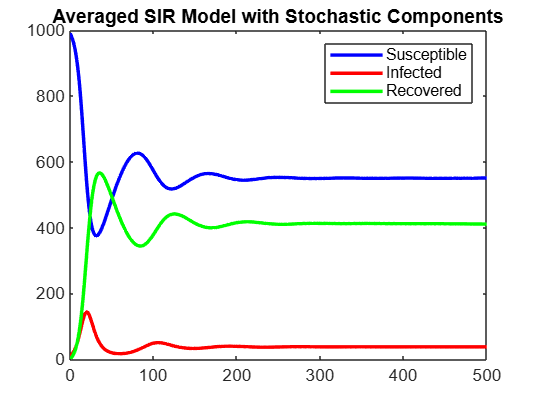


N = 1000;
dt = 1;
y = 4;
p = 0.5;
c = 1 / dt;
L = 0.025 / dt;
r = 0.275 / dt;
numsteps = 500;
sigma_S = 0.001;
sigma_I = 0.001;
sigma_R = 0.001;

I0 = 10;
S0 = N - I0;
R0 = 0;

num_simulations = 100;
results = zeros(3, numsteps + 1);


F = @(S, I, R) [-p * c * S * I / N + L * R;
                 p * c * S * I / N - r * I;
                 r * I - L * R];

for sim = 1:num_simulations
    x = zeros(3, numsteps + 1);
    x(:, 1) = [S0; I0; R0];

    for k = 1:numsteps
        curS = x(1, k);
        curI = x(2, k);
        curR = x(3, k);


        dX_det = F(curS, curI, curR);

        dW_S = sqrt(dt) * randn;
        dW_I = sqrt(dt) * randn;
        dW_R = sqrt(dt) * randn;

    dS_stoch = sigma_S * curS * dW_S;
    dI_stoch = sigma_I * curI * dW_I;
    dR_stoch = sigma_R * curR * dW_R;
    x(1,k + 1) = curS + dX_det(1) + dS_stoch;
    x(2,k + 1) = curI + dX_det(2) + dI_stoch;
    x(3,k + 1) = curR + dX_det(3) + dR_stoch;
    x(1, k + 1) = max(x(1, k + 1), 0);
    x(2, k + 1) = max(x(2, k + 1), 0);
    x(3, k + 1) = max(x(3, k + 1), 0);
    end

    results = results + x;  
end


average_results = results / num_simulations;


plot(0:numsteps, average_results(1, :), 'b', 'LineWidth', 2)
hold on
plot(0:numsteps, average_results(2, :), 'r', 'LineWidth', 2)
plot(0:numsteps, average_results(3, :), 'g', 'LineWidth', 2)
legend('Susceptible', 'Infected', 'Recovered')
title('Averaged SIR Model with Stochastic Components')
hold off